#                        Blind Source Separation

##                                            HW7-Section-1

                 Mohammadreza Arani         :::::::::::::         810100511

                                                           1402/02/24   

clear; clc; close all;

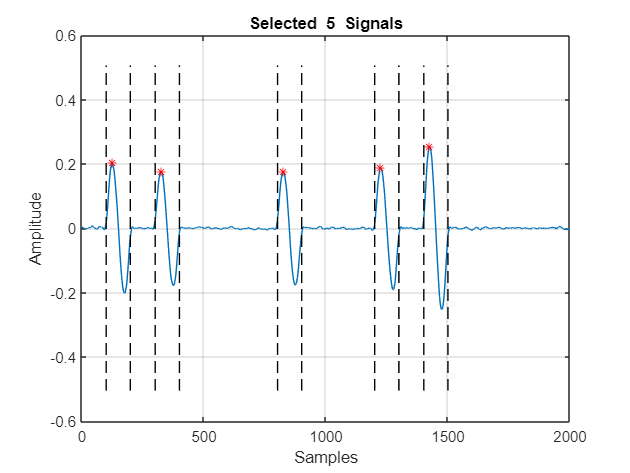

Data_hw7 = load("hw7.mat");
x1 = Data_hw7.x1;
L = 100;
K = 5;

windowSize = 31;
polyOrder = 2;
y1 = sgolayfilt(x1, polyOrder, windowSize);
figure()
plot(y1)
[Peaks_y1 , Locs_y1] = findpeaks(y1);

Good_Indices_Peaks =   find( ((Peaks_y1)>mean(abs(y1))) );
hold on
plot(Locs_y1(Good_Indices_Peaks),Peaks_y1(Good_Indices_Peaks),'r*');

% Loc_target_k = zeros(1,K);
Loc_target_k = Locs_y1(Good_Indices_Peaks);
Selected_Indices = zeros(2,K) ;
Signal_Selected_k = zeros(L,K);

for k=1:K
    Signal_Selected_k(:,k) = x1(Loc_target_k(1,k)-L/4+1:Loc_target_k(1,k)+3*L/4);
    Selected_Indices(:,k) = [ Loc_target_k(1,k)-L/4+1 ; Loc_target_k(1,k)+3*L/4 ];
    plot(Selected_Indices(1,k)*ones(1,10),linspace(-2*abs(min(y1)),2*max(abs(y1)),10)  ,'black--' );
    plot(Selected_Indices(2,k)*ones(1,10),linspace(-2*abs(min(y1)),2*max(abs(y1)),10)  ,'black--' );

end
grid on
title("Selected  "+K+"  Signals");
xlabel("Samples")
ylabel("Amplitude")
hold off

## Let's Do it in Frequency DOmain:

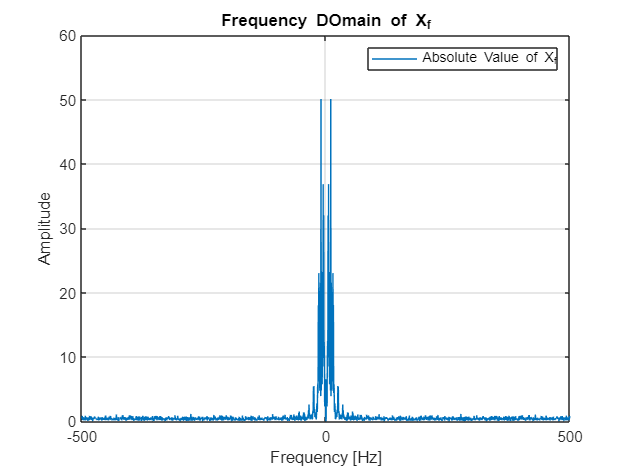

fs = 1e+03; %1000KHz
ts = 1/fs;
T_rec = length(x1)/fs;
delta_f = 1/T_rec; % frequency Resolution

freq = -fs/2:delta_f:fs/2-delta_f  ;
t = 0:ts:T_rec-ts;

X_f = fftshift(fft(x1));

figure()
plot(freq, abs(X_f));
grid on
title("Frequency DOmain of X_f")
legend("Absolute Value of X_f")
xlabel("Frequency [Hz]")
ylabel("Amplitude")

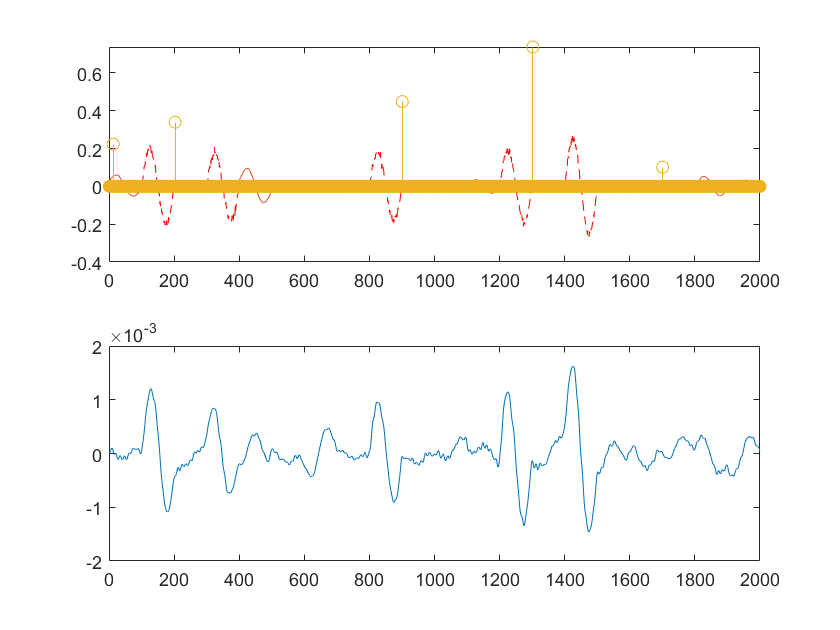

Indices_TO_Remove = find(abs(freq)>100)  ;
Y_F = X_f;
Y_F(Indices_TO_Remove) = 0;
T = length(Y_F);
Y_F = fftshift(Y_F)/norm(abs(Y_F));


% Random Generation of SHAI:
SHAI_f_hat = randn(size(Y_F))+1j*randn(size(Y_F)) ;


close all;
figure()
Rep_Error = zeros(1,IterMax);
Mean_Error =inf;
IterMax=150;
for i=1:IterMax
    % Step-1: S_f Update based on fixed SHAI_hat
    
    S_f_hat    = 0.5*( (Y_F)./(SHAI_f_hat) + conj( flip(Y_F) )./conj( flip(SHAI_f_hat) )    ); 
    % Step-2: Obtain "SHAI hat"
    YY_F_hat =zeros(size(Y_F));
    NonZero_Indexes = find(S_f_hat ~= 0);
    YY_F_hat(NonZero_Indexes) = Y_F(NonZero_Indexes)./S_f_hat(NonZero_Indexes);
    SHAI_hat = ifft((YY_F_hat),T);
    
    % Choose with deflation:
    TAU_vec = zeros(1,K);
    Temp_SHAI_HAT = SHAI_hat;

    for tau_ind=1:K
        [~,cache_Tau] = sort(abs(Temp_SHAI_HAT));
        TAU_vec(1,tau_ind) =  cache_Tau(1,end);
        if(cache_Tau(1,end)-L/2<1)
            Temp_SHAI_HAT(1,1:L) = 0;
        elseif(cache_Tau(1,end)+L/2>length(Temp_SHAI_HAT))
            Temp_SHAI_HAT(1,end:end-L) = 0;
        else
            Temp_SHAI_HAT(1,cache_Tau(1,end)-L/2:cache_Tau(1,end)+L/2) = 0;
        end
    end
%     [~ , TAU_vec ]  =  sort(abs(SHAI_hat));
%     TAU_vec   =   sort(TAU_vec(1,1:K));

    Alpha_Vec =   SHAI_hat(TAU_vec);
    Alpha_Vec = Alpha_Vec/norm(Alpha_Vec);

    SHAI_time = zeros(1,T);
    SHAI_time(TAU_vec) = abs(real(Alpha_Vec));
    

    SHAI_f_hat  = (fft(SHAI_time));
    SHAI_f_hat  = SHAI_f_hat/norm(abs(SHAI_f_hat),"fro");  % Normalize

    S_hat_Time  = real(ifft((S_f_hat)));

    X_hat_F = SHAI_f_hat.*S_f_hat;
    X_hat_F = X_hat_F/norm(abs(X_hat_F) , "fro" ); % Normalize

    X_hat_Time = conv(S_hat_Time,SHAI_time , "same");
    X_hat_Time = X_hat_Time/norm(X_hat_Time,"fro"); % Normalize
    % Error Calculation:
    Rep_Error(1,i) = norm( ifft(Y_F)/max(ifft(Y_F)) - ifft(SHAI_f_hat.*S_f_hat)/max(ifft(SHAI_f_hat.*S_f_hat))   , "fro") ;
    if(Mean_Error >Rep_Error(1,i) )
        Mean_Error = Rep_Error(1,i);
        Best_Indice = i;
        Best_S_hat_Time = S_hat_Time;
        Best_SHAI_f_hat = SHAI_f_hat;
        Best_SHAI_time = SHAI_time;
        Best_TAU_vec = TAU_vec;
        Best_Alpha_Vec = Alpha_Vec;
        Best_X_hat_F = X_hat_F;
    end
    %close all;

    drawnow
    subplot(2,1,1)
    plot(x1,'r--');
    hold on
    plot(X_hat_Time);
    stem(SHAI_time);
    hold off;
    subplot(2,1,2)
    plot(real(ifft(X_hat_F)));
   
end

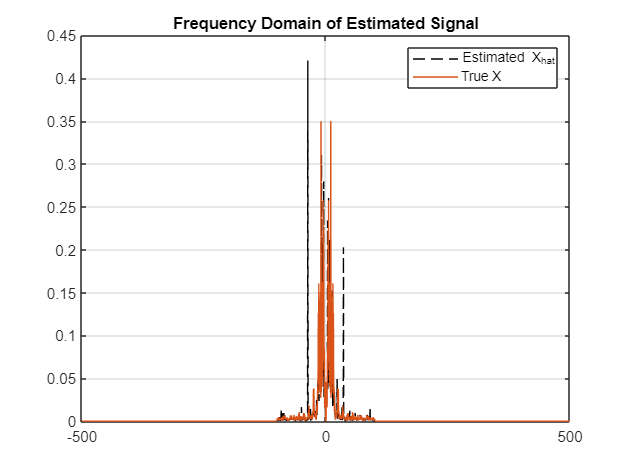


figure()
plot(freq,abs(fftshift(X_hat_F)) , 'black--');
grid on
title("Frequency Domain of Estimated Signal")
hold on
plot(freq,abs(fftshift(Y_F)));
hold off
legend("Estimated X_{hat}" , "True X")

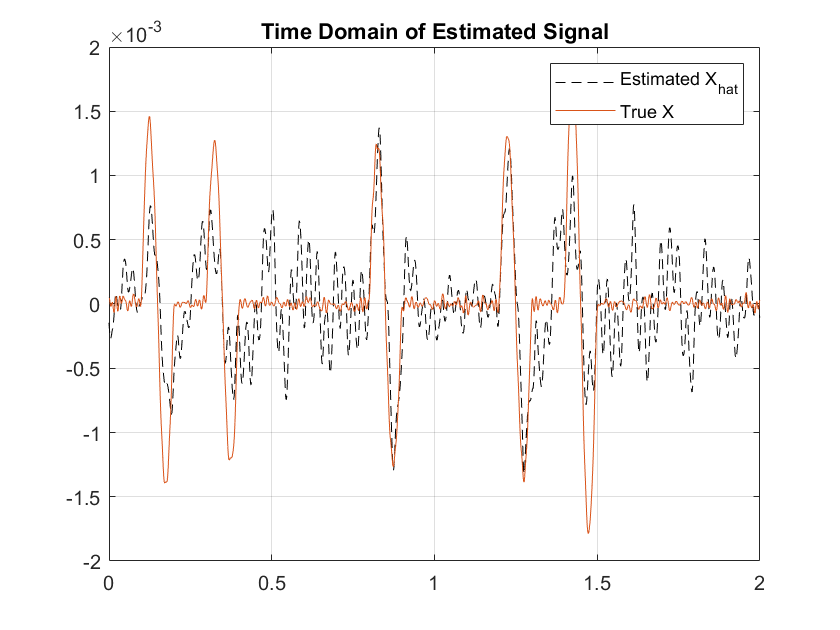

figure()
plot(t,real(ifft((X_hat_F))) , 'black--');
grid on
title("Time Domain of Estimated Signal")
hold on
plot(t,ifft((Y_F)));
hold off
legend("Estimated X_{hat}" , "True X")

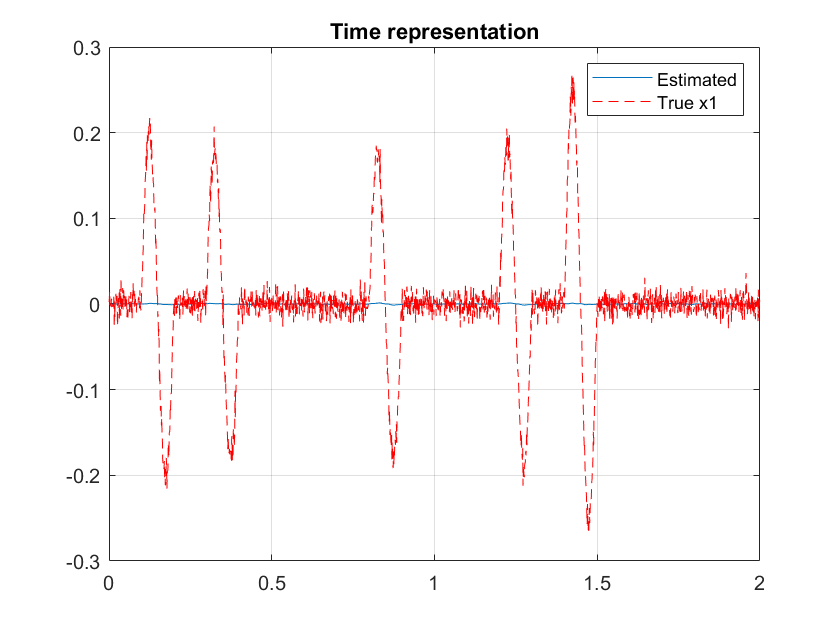


t = 0:ts:T_rec-ts;
figure()
plot(t,real(ifft((X_hat_F))))
hold on
plot(t,x1,'r--')
grid on
title("Time representation")
legend("Estimated", "True x1")

## Plot The Best Result:

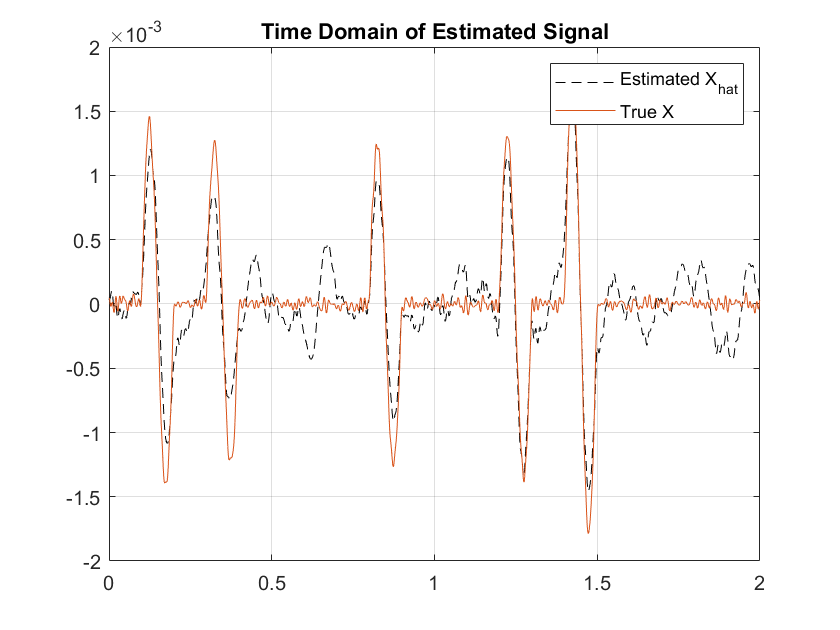

figure()
plot(t,real(ifft((Best_X_hat_F))) , 'black--');
grid on
title("Time Domain of Estimated Signal")
hold on
plot(t,ifft((Y_F)));
hold off
legend("Estimated X_{hat}" , "True X")

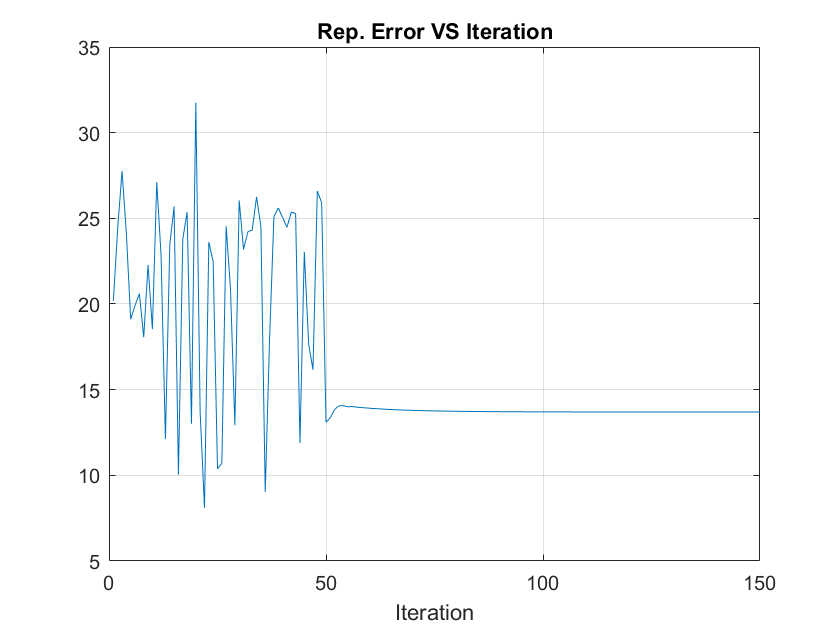

figure()
plot(Rep_Error)
grid on
xlabel("Iteration")
title("Rep. Error VS Iteration")